# Bioingeniería II - 2019-3

Cuarto Taller

20 de febrero de 2020

Diana Carolina Diaz Cabra cód: 20151005010

Jeison Estiven García Torres cód: 20151005015

Nicolás Rodríguez Daza cód: 20151005022

# Objetivo

Determinar los filtros eléctricos (tipos, cantidad necesaria y especificaciones de cada uno), que se deben de utilizar en un amplificador de señales ECG.

# Actividades a desarrollar

Organizados en grupos de tres personas, procedan a desarrollar las actividades consignadas a continuación. El desarrollo de cada actividad debe registrarse en este mismo archivo. Al final de la clase deben enviar este archivo (en formato mlx) junto con su versión en pdf al correo: hilopezc@udistrital.edu.co.

## Primera actividad: espectro de las señales capturadas en el laboratorio.

Realice la carga, en MATLAB, de los archivos csv correspondientes a las señales de los amplificadores de instrumentación, que capturaron en el laboratorio. Utilicen la función `espectrofft` para visualizar un solo periodo de cada señal y limitar el espectro positivo a 125 Hz.

senal = "INA(CAROLINA)S";
switch senal
    case "INA(JEISON)"%
        archivo = 'ina(JEISON).csv';
        columna = 2; 
        intervalo = 155:355; 
    case "INA(JEISON)S"%
        archivo = 'ina(JEISON)s.csv';
        columna = 2; 
        intervalo = 142:342;
    case "AD(JEISON)"%
        archivo = 'ad(JEISON).csv';
        columna = 2; 
        intervalo = 40:240;
    case "AD(JEISON)S"%
        archivo = 'ad(JEISON)s.csv';
        columna = 2; 
        intervalo = 140:340;
    case "INA(CAROLINA)"%            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(CAROLINA).csv';
        columna = 2; 
        intervalo = 190:388; 
    case "INA(CAROLINA)S"%
        archivo = 'ina(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 160:360; 
    case "AD(CAROLINA)"%
        archivo = 'ad(CAROLINA).csv';
        columna = 2; 
        intervalo = 138:338; 
    case "AD(CAROLINA)S"%
        archivo = 'ad(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 240:440; 
    case "INA(NICOLAS)"%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(NICOLAS).csv';
        columna = 2; 
        intervalo = 150:350; 
    case "INA(NICOLAS)S"%
        archivo = 'ina(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 180:380; 
    case "AD(NICOLAS)"%
        archivo = 'ad(NICOLAS).csv';
        columna = 2; 
        intervalo = 315:515; 
    case "AD(NICOLAS)S"%
        archivo = 'ad(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 133:333; 
end    
espectrofft(archivo,columna,125,intervalo);

## Segunda actividad: Filtro Pasabajos

Utilice el código editado en la primera actividad, correspondiente al `switch-case`, para reemplazarlo en la sección encerrada por comentarios que se muestra a continuación (no incluyan la línea de comando que usa `espectrofft`):

senal = "INA(CAROLINA)S";
switch senal
    case "INA(JEISON)"%
        archivo = 'ina(JEISON).csv';
        columna = 2; 
        intervalo = 155:355; 
    case "INA(JEISON)S"%
        archivo = 'ina(JEISON)s.csv';
        columna = 2; 
        intervalo = 142:342;
    case "AD(JEISON)"%
        archivo = 'ad(JEISON).csv';
        columna = 2; 
        intervalo = 40:240;
    case "AD(JEISON)S"%
        archivo = 'ad(JEISON)s.csv';
        columna = 2; 
        intervalo = 140:340;
    case "INA(CAROLINA)"%            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(CAROLINA).csv';
        columna = 2; 
        intervalo = 190:388; 
    case "INA(CAROLINA)S"%
        archivo = 'ina(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 160:360; 
    case "AD(CAROLINA)"%
        archivo = 'ad(CAROLINA).csv';
        columna = 2; 
        intervalo = 138:338; 
    case "AD(CAROLINA)S"%
        archivo = 'ad(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 240:440; 
    case "INA(NICOLAS)"%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(NICOLAS).csv';
        columna = 2; 
        intervalo = 150:350; 
    case "INA(NICOLAS)S"%
        archivo = 'ina(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 180:380; 
    case "AD(NICOLAS)"%
        archivo = 'ad(NICOLAS).csv';
        columna = 2; 
        intervalo = 315:515; 
    case "AD(NICOLAS)S"%
        archivo = 'ad(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 133:333; 
end    

Paso seguido, modifiquen a su gusto los valores de frecuencia de corte y orden del filtro pasabajo. Identifiquen ambos parámetros y escríbanlos a continuación: $f_c =$30  y $\textrm{orden} = $4.

frecuenciamaxima = 54;
fc = 30;
orden = 4;
[Y,g,t,Fs] = transformadafft(archivo,columna,125,intervalo); % Devuelve la transformada
Y = fftshift(Y);
L = numel(Y);
f = linspace(-Fs/2,Fs/2,L);
H = filtrolp(f,fc,orden); % Filtro pasabajos
x = (L+1)/2:(L+1)/2+frecuenciamaxima*L/Fs;

figure();
subplot(2,2,1)
superplot(t,g,...
    'Señal ruidosa',...
    '$\frac{t}{\textrm{s}}$',...
    '$g(t)$');

subplot(2,2,2);
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    ['Filtro de orden ',num2str(orden),...
    ' y f_c = ',num2str(fc)],...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H_{\textrm{LP}}(f)\vert\vert$');

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y))/(2*pi);
superplot(t,y,...
    'Señal ECG filtrada',...
    '$t$','$g(t)$');

## Tercera actividad

Utilice el código editado en la primera actividad, correspondiente al `switch-case`, para reemplazarlo en la sección encerrada por comentarios que se muestra a continuación (no incluyan la línea de comando que usa `espectrofft`):

senal = "INA(CAROLINA)S";
switch senal
    case "INA(JEISON)"%
        archivo = 'ina(JEISON).csv';
        columna = 2; 
        intervalo = 155:355; 
    case "INA(JEISON)S"%
        archivo = 'ina(JEISON)s.csv';
        columna = 2; 
        intervalo = 142:342;
    case "AD(JEISON)"%
        archivo = 'ad(JEISON).csv';
        columna = 2; 
        intervalo = 40:240;
    case "AD(JEISON)S"%
        archivo = 'ad(JEISON)s.csv';
        columna = 2; 
        intervalo = 140:340;
    case "INA(CAROLINA)"%            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(CAROLINA).csv';
        columna = 2; 
        intervalo = 190:388; 
    case "INA(CAROLINA)S"%
        archivo = 'ina(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 160:360; 
    case "AD(CAROLINA)"%
        archivo = 'ad(CAROLINA).csv';
        columna = 2; 
        intervalo = 138:338; 
    case "AD(CAROLINA)S"%
        archivo = 'ad(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 240:440; 
    case "INA(NICOLAS)"%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(NICOLAS).csv';
        columna = 2; 
        intervalo = 150:350; 
    case "INA(NICOLAS)S"%
        archivo = 'ina(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 180:380; 
    case "AD(NICOLAS)"%
        archivo = 'ad(NICOLAS).csv';
        columna = 2; 
        intervalo = 315:515; 
    case "AD(NICOLAS)S"%
        archivo = 'ad(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 133:333; 
end  

Paso seguido, modifiquen a su gusto los valores de frecuencia de corte y orden del filtro pasaalto. Identifiquen ambos parámetros y escríbanlos a continuación: $f_c =$0.35 y $\textrm{orden} = $1.

frecuenciamaxima = 100;
fc = 0.35;
orden = 1;
[Y,g,t,Fs] = transformadafft(archivo,columna,125,intervalo,0); % Incluye el nivel DC
Y = fftshift(Y);
L = numel(Y);
f = linspace(-Fs/2,Fs/2,L);
H = filtrohp(f,fc,orden); % Filtro pasaaltos
x = (L+1)/2:(L+1)/2+frecuenciamaxima*L/Fs;

figure();
subplot(2,2,1)
superplot(t,g,...
    'Señal ruidosa',...
    '$\frac{t}{\textrm{s}}$',...
    '$g(t)$');

subplot(2,2,2);
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    ['Filtro de orden ',num2str(orden),...
    ' y f_c = ',num2str(fc)],...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H_{\textrm{LP}}(f)\vert\vert$');

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y))/(2*pi);
superplot(t,y,...
    'Señal ECG filtrada',...
    '$t$','$g(t)$');

## Cuarta actividad: Filtro pasabanda

Utilice los códigos de las actividades anteriores, y las funciones `filtrolp` y `filtrohp`, para mostrar el resultado de aplicar los dos filtros en cascada:

senal = "INA(CAROLINA)S";
switch senal
    case "INA(JEISON)"%
        archivo = 'ina(JEISON).csv';
        columna = 2; 
        intervalo = 155:355; 
    case "INA(JEISON)S"%
        archivo = 'ina(JEISON)s.csv';
        columna = 2; 
        intervalo = 142:342;
    case "AD(JEISON)"%
        archivo = 'ad(JEISON).csv';
        columna = 2; 
        intervalo = 40:240;
    case "AD(JEISON)S"%
        archivo = 'ad(JEISON)s.csv';
        columna = 2; 
        intervalo = 140:340;
    case "INA(CAROLINA)"%            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(CAROLINA).csv';
        columna = 2; 
        intervalo = 190:388; 
    case "INA(CAROLINA)S"%
        archivo = 'ina(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 160:360; 
    case "AD(CAROLINA)"%
        archivo = 'ad(CAROLINA).csv';
        columna = 2; 
        intervalo = 138:338; 
    case "AD(CAROLINA)S"%
        archivo = 'ad(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 240:440; 
    case "INA(NICOLAS)"%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(NICOLAS).csv';
        columna = 2; 
        intervalo = 150:350; 
    case "INA(NICOLAS)S"%
        archivo = 'ina(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 180:380; 
    case "AD(NICOLAS)"%
        archivo = 'ad(NICOLAS).csv';
        columna = 2; 
        intervalo = 315:515; 
    case "AD(NICOLAS)S"%
        archivo = 'ad(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 133:333; 
end 
frecuenciamaxima = 125;
fl = 30;
fh = 0.35;
ordenLp = 4;
ordenHp = 1;
[Y,g,t,Fs] = transformadafft(archivo,columna,125,intervalo);
Y = fftshift(Y);
L = numel(Y);
f = linspace(-Fs/2,Fs/2,L);
Hlp = filtrolp(f,fl,ordenLp);
Hhp = filtrohp(f,fh,ordenHp);
H = Hlp .* Hhp; % Filtros conectados en Tandem
x = (L+1)/2:(L+1)/2+frecuenciamaxima*L/Fs;

figure();
subplot(2,2,1)
superplot(t,g,...
    'Señal ruidosa',...
    '$\frac{t}{\textrm{ms}}$',...
    '$g(t)$');

subplot(2,2,2);
magnitud = abs(Hlp);
superplot(f(x),magnitud(x));
hold on;
magnitud = abs(Hhp);
superplot(f(x),magnitud(x));
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    'Magnitud de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H(f)\vert\vert$');
hold off;
axis([0,frecuenciamaxima,-0.1,1.1]);

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y));
superplot(t,y,...
    'Señal ECG filtrada',...
    '$t$','$g(t) = g(t+1\textrm{s})$');

## Quinta actividad: Filtro rechazabanda de banda ancha

Utilice el código editado en la primera actividad, correspondiente al `switch-case`, para reemplazarlo en la sección encerrada por comentarios que se muestra a continuación (no incluyan la línea de comando que usa `espectrofft`):

senal = "INA(CAROLINA)S";
switch senal
    case "INA(JEISON)"%
        archivo = 'ina(JEISON).csv';
        columna = 2; 
        intervalo = 155:355; 
    case "INA(JEISON)S"%
        archivo = 'ina(JEISON)s.csv';
        columna = 2; 
        intervalo = 142:342;
    case "AD(JEISON)"%
        archivo = 'ad(JEISON).csv';
        columna = 2; 
        intervalo = 40:240;
    case "AD(JEISON)S"%
        archivo = 'ad(JEISON)s.csv';
        columna = 2; 
        intervalo = 140:340;
    case "INA(CAROLINA)"%            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(CAROLINA).csv';
        columna = 2; 
        intervalo = 190:388; 
    case "INA(CAROLINA)S"%
        archivo = 'ina(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 160:360; 
    case "AD(CAROLINA)"%
        archivo = 'ad(CAROLINA).csv';
        columna = 2; 
        intervalo = 138:338; 
    case "AD(CAROLINA)S"%
        archivo = 'ad(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 240:440; 
    case "INA(NICOLAS)"%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(NICOLAS).csv';
        columna = 2; 
        intervalo = 150:350; 
    case "INA(NICOLAS)S"%
        archivo = 'ina(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 180:380; 
    case "AD(NICOLAS)"%
        archivo = 'ad(NICOLAS).csv';
        columna = 2; 
        intervalo = 315:515; 
    case "AD(NICOLAS)S"%
        archivo = 'ad(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 133:333; 
end 

Paso seguido, modifiquen a su gusto los valores de frecuencia de corte y orden de los filtros pasabajos y pasaaltos. Identifiquen ambos parámetros y escríbanlos a continuación: $f_l =$50    $f_h =$70 y $\textrm{orden} = $5.

frecuenciamaxima = 125;
fl = 50;
fh = 70;
orden = 5;
[Y,g,t,Fs] = transformadafft(archivo,columna,125,intervalo);
Y = fftshift(Y);
L = numel(Y);
f = linspace(-Fs/2,Fs/2,L);
Hlp = filtrolp(f,fl,orden);
Hhp = filtrohp(f,fh,orden);
H = Hlp + Hhp; % Filtros conectados en Tandem
x = (L+1)/2:(L+1)/2+frecuenciamaxima*L/Fs;

figure();
subplot(2,2,1)
superplot(t,g,...
    'Señal ruidosa',...
    '$\frac{t}{\textrm{ms}}$',...
    '$g(t)$');

subplot(2,2,2);
magnitud = abs(Hlp);
superplot(f(x),magnitud(x));
hold on;
magnitud = abs(Hhp);
superplot(f(x),magnitud(x));
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    'Magnitud de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H(f)\vert\vert$');
hold off;
axis([0,frecuenciamaxima,-0.1,1.1]);

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y));
superplot(t,y,...
    'Señal ECG filtrada',...
    '$t$','$g(t) = g(t+1\textrm{s})$');

## Sexta actividad: función f`iltronotch`

Codifique en MATLAB una función que implemente el filtro *notch* que investigó en sesiones pasadas. La función se debe de llamar `filtronotch` y debe tener la misma estructura de las funciones `filtrolp` y `filtrohp` que se utilizaron en las actividades anteriores:

Los parámetros de entrada de la función podrían ser:

- `frecuencias`: un vector con las frencuencias en las que se va a evaluar la función de transferencia del filtro.

- `fc`: frecuencia central.

- Q: factor de calidad.

El parámetro de salida debe ser:

- H: un vector fila con los valores de la función de transferencia evaluada en los valores dados por el vector frecuencias.

Acompañe la función con la ecuación de la función de transferencia:


$$H_N(s)=\frac{s^2+\omega_0^2}{s^2+\frac{\omega_0}{Q}s+\omega_0^2}$$


senal = "INA(CAROLINA)S";
switch senal
    case "INA(JEISON)"%
        archivo = 'ina(JEISON).csv';
        columna = 2; 
        intervalo = 155:355; 
    case "INA(JEISON)S"%
        archivo = 'ina(JEISON)s.csv';
        columna = 2; 
        intervalo = 142:342;
    case "AD(JEISON)"%
        archivo = 'ad(JEISON).csv';
        columna = 2; 
        intervalo = 40:240;
    case "AD(JEISON)S"%
        archivo = 'ad(JEISON)s.csv';
        columna = 2; 
        intervalo = 140:340;
    case "INA(CAROLINA)"%            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(CAROLINA).csv';
        columna = 2; 
        intervalo = 190:388; 
    case "INA(CAROLINA)S"%
        archivo = 'ina(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 160:360; 
    case "AD(CAROLINA)"%
        archivo = 'ad(CAROLINA).csv';
        columna = 2 ;
        intervalo = 138:338; 
    case "AD(CAROLINA)S"%
        archivo = 'ad(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 240:440; 
    case "INA(NICOLAS)"%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(NICOLAS).csv';
        columna = 2; 
        intervalo = 150:350; 
    case "INA(NICOLAS)S"%
        archivo = 'ina(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 180:380; 
    case "AD(NICOLAS)"%
        archivo = 'ad(NICOLAS).csv';
        columna = 2; 
        intervalo = 315:515; 
    case "AD(NICOLAS)S"%
        archivo = 'ad(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 133:333; 
end 
frecuenciamaxima = 125;
fc= 60;
Q = 0.5;
[Y,g,t,Fs] = transformadafft(archivo,columna,125,intervalo);
Y = fftshift(Y);
L = numel(Y);
f = linspace(-Fs/2,Fs/2,L);
HN= filtronotch(f,fc,Q);
H = HN; % Filtros conectados en Tandem
x = (L+1)/2:(L+1)/2+frecuenciamaxima*L/Fs;

figure();
subplot(2,2,1)
superplot(t,g,...
    'Señal ruidosa',...
    '$\frac{t}{\textrm{ms}}$',...
    '$g(t)$');

subplot(2,2,2);
magnitud = abs(HN);
superplot(f(x),magnitud(x));
hold on;
magnitud = abs(HN);
superplot(f(x),magnitud(x));
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    'Magnitud de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H(f)\vert\vert$');
hold off;
axis([0,frecuenciamaxima,-0.1,1.1]);

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y));
superplot(t,y,...
    'Señal ECG filtrada',...
    '$t$','$g(t) = g(t+1\textrm{s})$');
magnitud = abs(Hlp);
superplot(f(x),magnitud(x));
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    'Magnitud de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H(f)\vert\vert$');
hold off;
axis([0,frecuenciamaxima,-0.1,1.1]);

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y));
superplot(t,y,...
    'Señal ECG filtrada',...
    '$t$','$g(t) = g(t+1\textrm{s})$');

## Séptima Actividad: Espectros de magnitud y fase del filtro *notch*.

Realice la gráfica de los espectros de magnitud y fase, de los valores obtenidos con la función de la actividad 6. Utilice el siguiente ejemplo:

fl = 50;
fh = 70;
orden = 5;
frecuenciamaxima = 125;

figure();
L = 1001;
f = linspace(-(L-1)/2,(L-1)/2,L);
Hlp = filtrolp(f,fl,orden);
Hhp = filtrohp(f,fh,orden);
H = Hlp + Hhp; % Función de transferencia del filtro rechazabanda
x = (L+1)/2:(L+1)/2+frecuenciamaxima;

subplot(2,1,1);
magnitud = abs(Hlp);
superplot(f(x),magnitud(x));
hold on;
magnitud = abs(Hhp);
superplot(f(x),magnitud(x));
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    'Magnitud de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H(f)\vert\vert$');
hold off;
axis([0,frecuenciamaxima,-0.1,1.1]);
legend('LP','HP','LP+HP');
subplot(2,1,2);
fase = angle(Hlp);
superplot(f(x),fase(x));
hold on;
fase = angle(Hhp);
superplot(f(x),fase(x));
fase = angle(H);
superplot(f(x),fase(x),...
    'Fase de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\textrm{Arg}\{ H(f)\}$');
hold off;
axis([0,frecuenciamaxima,-pi,pi]);
yticks(-pi:pi/2:pi);
yticklabels({'$-\pi$','$-\pi/2$','$0$','$\pi/2$','$\pi$'});
legend('LP','HP','LP+HP');

## Octava actividad: filtrado completo.

De acuerdo al análisis de los resultados, de las actividades anteriores, proceda a editar el código de la actividad 5, de manera tal que se apliquen todos los filtros que considere necesarios

 Se escoge el uso del filtro Notch con fc = 60 Hz y un factor de calidad Q = 0.5 en conjunto con un filtro pasa altos con fc = 0.35Hz y orden = 1.

senal = "INA(CAROLINA)S";
switch senal
    case "INA(JEISON)"%
        archivo = 'ina(JEISON).csv';
        columna = 2; 
        intervalo = 155:355; 
    case "INA(JEISON)S"%
        archivo = 'ina(JEISON)s.csv';
        columna = 2; 
        intervalo = 142:342;
    case "AD(JEISON)"%
        archivo = 'ad(JEISON).csv';
        columna = 2; 
        intervalo = 40:240;
    case "AD(JEISON)S"%
        archivo = 'ad(JEISON)s.csv';
        columna = 2; 
        intervalo = 140:340;
    case "INA(CAROLINA)"%            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(CAROLINA).csv';
        columna = 2; 
        intervalo = 190:388; 
    case "INA(CAROLINA)S"%
        archivo = 'ina(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 160:360; 
    case "AD(CAROLINA)"%
        archivo = 'ad(CAROLINA).csv';
        columna = 2; 
        intervalo = 138:338; 
    case "AD(CAROLINA)S"%
        archivo = 'ad(CAROLINA)s.csv';
        columna = 2; 
        intervalo = 240:440; 
    case "INA(NICOLAS)"%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        archivo = 'ina(NICOLAS).csv';
        columna = 2; 
        intervalo = 150:350; 
    case "INA(NICOLAS)S"%
        archivo = 'ina(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 180:380; 
    case "AD(NICOLAS)"%
        archivo = 'ad(NICOLAS).csv';
        columna = 2; 
        intervalo = 315:515; 
    case "AD(NICOLAS)S"%
        archivo = 'ad(NICOLAS)s.csv';
        columna = 2; 
        intervalo = 133:333; 
end    
frecuenciamaxima = 125;
fc= 60;
Q = 0.5;
[Y,g,t,Fs] = transformadafft(archivo,columna,125,intervalo);
Y = fftshift(Y);
L = numel(Y);
f = linspace(-Fs/2,Fs/2,L);
HN= filtronotch(f,fc,Q);

fc= 0.35;
orden=1;
HP= filtrohp(f,fc,orden);


H = HN.*HP; % Filtros conectados en Tandem
x = (L+1)/2:(L+1)/2+frecuenciamaxima*L/Fs;

figure();
subplot(2,2,1)
superplot(t,g,...
    'Señal ruidosa',...
    '$\frac{t}{\textrm{ms}}$',...
    '$g(t)$');

subplot(2,2,2);
magnitud = abs(HN);
superplot(f(x),magnitud(x));
hold on;
magnitud = abs(HN);
superplot(f(x),magnitud(x));
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    'Magnitud de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H(f)\vert\vert$');
hold off;
axis([0,frecuenciamaxima,-0.1,1.1]);

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y));
superplot(t,y,...
    'Señal ECG filtrada',...
    '$t$','$g(t) = g(t+1\textrm{s})$');
magnitud = abs(Hlp);
superplot(f(x),magnitud(x));
magnitud = abs(H);
superplot(f(x),magnitud(x),...
    'Magnitud de H(f)',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert H(f)\vert\vert$');
hold off;
axis([0,frecuenciamaxima,-0.1,1.1]);

subplot(2,2,3);
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold on;
Y = H.*Y;
magnitud = abs(Y);
superstem(f(x),magnitud(x),...
    'Espectro Positivo de la Señal ECG',...
    '$\frac{f}{\textrm{Hz}}$',...
    '$\vert\vert G(f)\vert\vert$');
hold off;
legend('Sin filtrar','Filtrado');
subplot(2,2,4)
y = L*ifft(ifftshift(Y));
superplot(t,y,...
    'Señal ECG filtrada',...

# Conclusiones

- Para el caso del filtro pasa-altos cuyo objetivo en este caso es eliminar la componente DC de la señal, se selecciona una frecuencia de corte inferior a la frecuencia a la cual está ubicada la componente fundamental del espectro de la señal ECG, sin embargo, pensando en la posterior implementación se contemplaron los valores de los componentes para limitar la frecuencia de corte más baja a la cual ubicar el filtro, en adición a ello, el orden del filtro selecciono al observar que un filtro de primer orden cumplía con el objetivo y por ende seria innecesario incrementar el orden y a su vez el número de componentes necesarios.

- Se determina que para eliminar el ruido de la componente de 60 Hz lo más adecuado es la implementación de un filtro Notch debido a que elimina menos información espectral con respecto al filtro pasa bajos, el cual nos elimina la información de frecuencias altas, y tiene una mayor selectividad que el filtro rechaza banda (Filtro pasa bajos y pasa altos en Tandem), de igual forma que el filtro pasa banda el cual que no tiene ningun efecto en las compenentes de 60Hz.

# Funciones

Función de ejemplo. Pueden colocar las instrucciones debajo de cada actividad, o invocar funciones y registrarlas en esta sección.

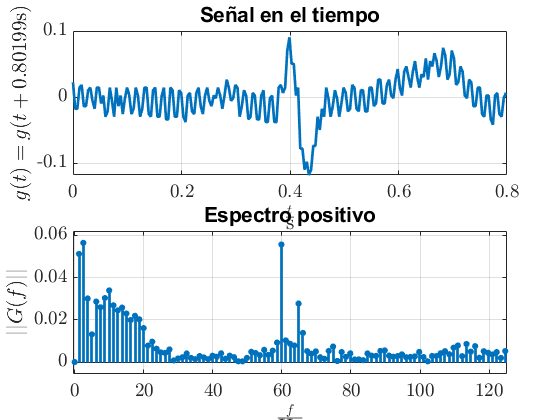

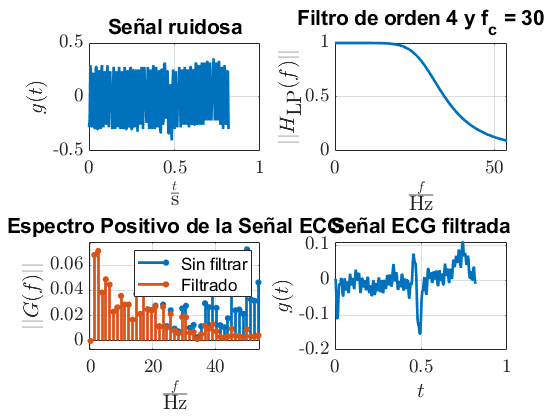

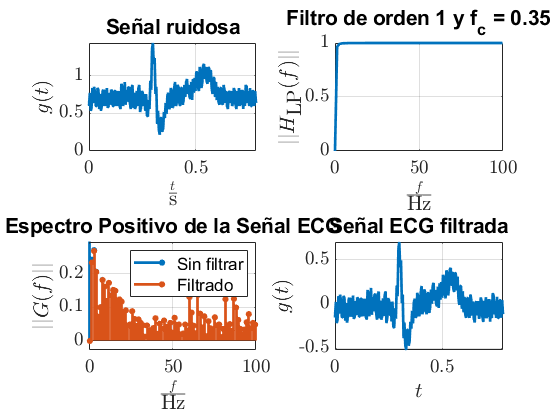

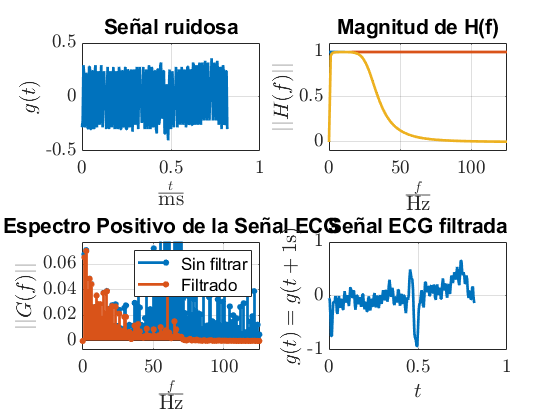

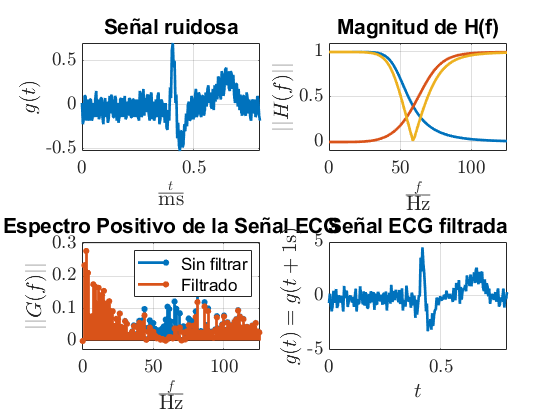


function H = filtrolp(frecuencias,fc,orden)
    n = frecuencias;
    coeficientes = butterworthcoef(orden);
    
    H = 1;
    if orden > 0    
        for m = 1:numel(coeficientes)
            H = H.*(4*pi*pi*fc*fc)./...
                ((-4*pi*pi.*n.*n)+ (4*pi*pi*n*fc.*coeficientes(m)).*i + 4*pi*pi*fc*fc);
        end
        
        if mod(orden,2) ~= 0 %si el orden del filtro es impar
            H = H.*(2*pi*fc)./(2*pi*n*i+2*pi*fc);
        end
    end
end

function y = butterworthcoef(n)
    if (n/2)==(floor(n/2))
        maximo = n/2;
    else
        maximo = (n-1)/2;    
    end
        y = zeros(1,maximo);        
    for k = 1:maximo
        y(k) = -2*cos((2*k+n-1)*pi/(2*n));
    end
end


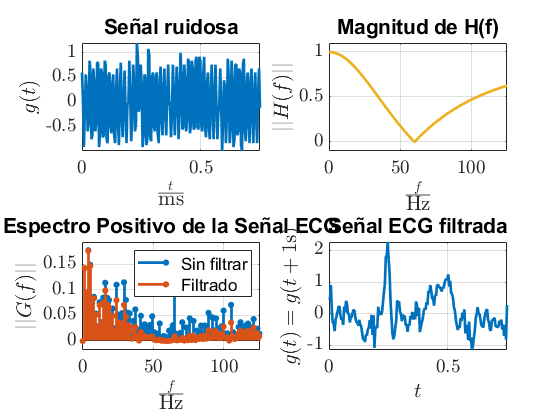

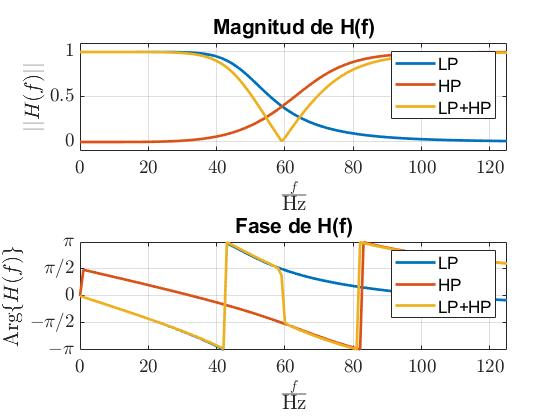

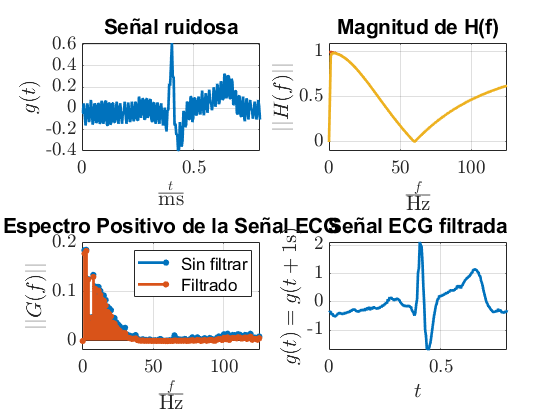

function [HN] = filtronotch(frecuencias,fc,Q)
    n = frecuencias;
    s=2*pi*n*1i;

    wo=2*pi*fc;
    HN = (s.^2+wo^2)./(s.^2+s*wo/Q+wo^2);
end